# Frequency Domain Decomposition (FDD)

In this example, Frequency Domain Decomposition (FDD) is used to identify modal frequencies and generate mode shapes from a numerical simulation of a plucked string.

## Taut String Simulation

Simulate the motion of a string impulsed at the center using the function `stringFDTD` that is included with the OoMA toolbox.

T = 100; % string tension
x = linspace(0,0.25,20); % string spatial discretization vector
rho = 0.1; % string mass per unit length
c = 1; % viscous damping coefficient
td = 1; % time duration to simulate
Y = [];
rng(1)
% "pluck" the string several times in random locations, concatenating the outputs
for i = 1:4
    % force (impulse) applied at random location but not endpoints
    f_idx = randi(length(x)-2)+1; 
    [y,t] = stringFDTD(T,x,rho,c,td,f_idx);
    Y = [Y y];
end

## Frequency Domain Decomposition

Call `fdd` on the data obtained from the simulation. Use the "Select Peak" button to choose peaks in the CMIF curve which correspond to modal frequencies.

dt = t(2)-t(1); % sampling period
fs = 1/dt; % sampling frequency
[SV,F,Phi,I,SV_nums] = fdd(Y,[],fs,[]);

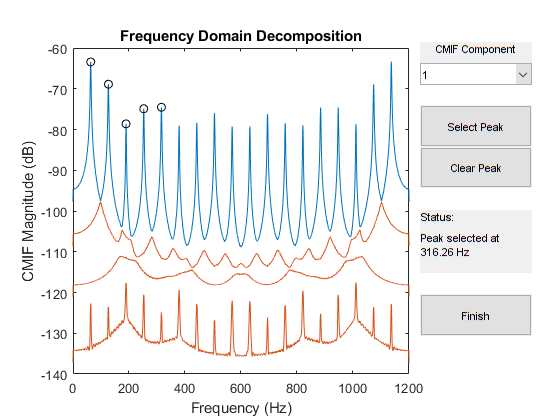

Here we show the first five peaks being selected. Click the "Finish" button or close the window once the desired peaks have been selected.

## Mode Shapes

Plot the mode shapes. In this example we only selected the first five peaks using `fdd`.

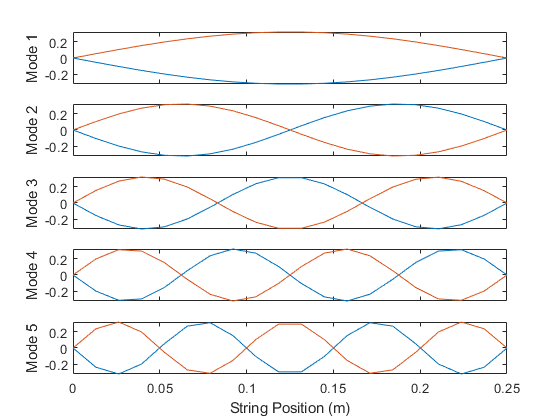

clf
for i = 1:size(Phi,2)
    subplot(size(Phi,2),1,i)
    z = Phi(:,i);
    plot(x,abs(z).*cos(angle(z)))
    hold on
    plot(x,-abs(z).*cos(angle(z)))
    hold off
    
    if i == size(Phi,2)
        xlabel('String Position (m)')
    else
        xticklabels([])
    end
    axis tight
    ylabel(['Mode ' num2str(i)])
end

Also list the frequencies of the mode shapes.

F(I)

ans =    63.3691
  126.7382
  189.5205
  252.8896
  316.2586


We see that the modal frequencies occur in multiples of the first (fundamental) frequency, which is consistent with the vibration model of a fixed-fixed taut string.